# Figure 2.2 

#### Set up the graph

source = [1 1];
target = [1 2];
G = quantumGraph(source,target,[pi 2],'nxVec',[8 4]);
G.addPlotCoords(@lassoPlotCoords);

Note that the same graph could be constructed using the **lasso template.**

#### (a) Plot the layout

This lacks some of the formatting, namely the markers at the discretization points. This is difficult to achieve without interactively editing the plot. Changing the orientation of the graph 

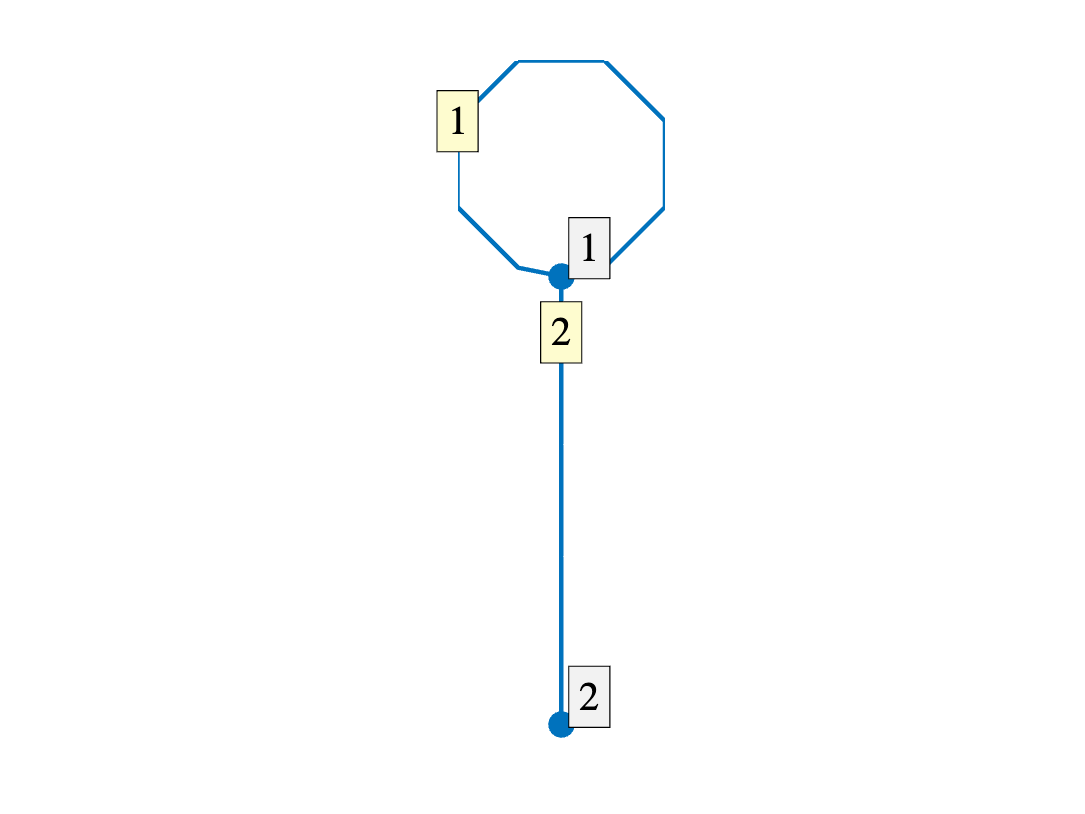

G.plot('layout')

#### (b) Spy on the matrix

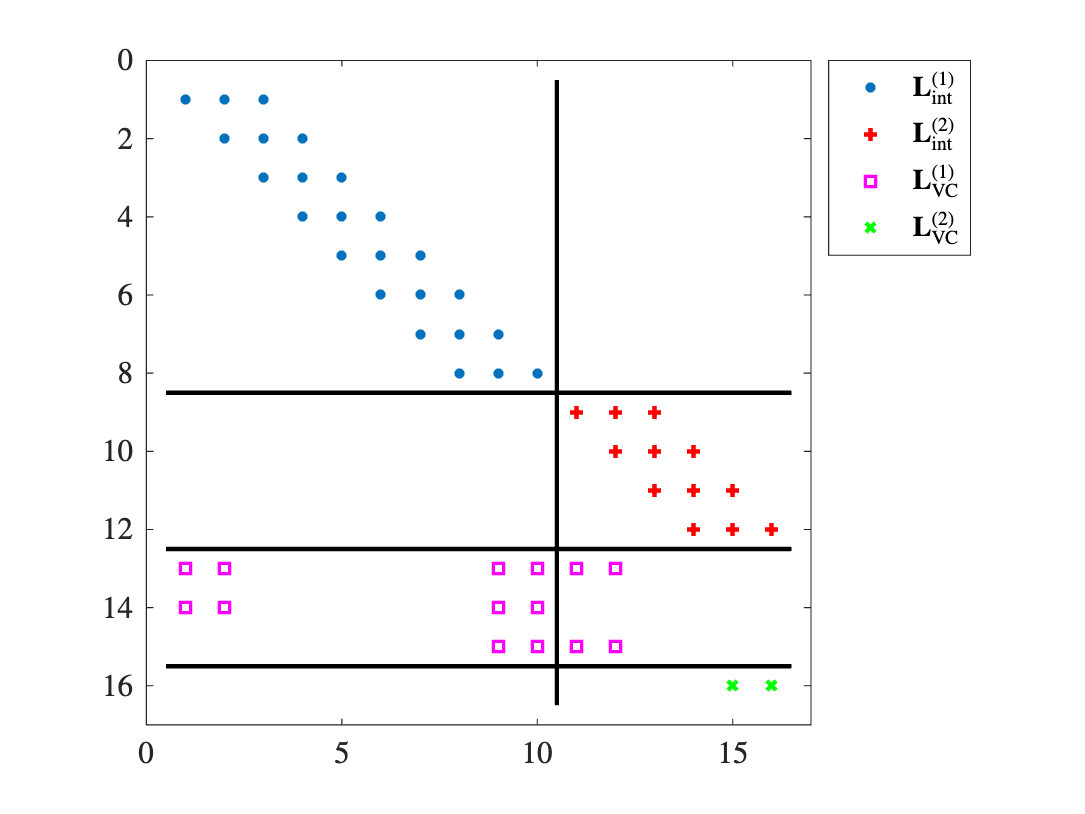

L = G.laplacianMatrixWithVC;
[Mx,My]=meshgrid(1:length(L));
spy(L.*(My<=8))
hold on
spy(L.*(8<My).*(My<=12),'r+');
spy(L.*(13<=My).*(My<16),'ms')
spy(L.*(My==16),'gx')
xlabel('')

plot([.5 16.5],(8.5)*[1 1],'k')
plot([.5 16.5],12.5*[1 1],'k')
plot([.5 16.5],15.5*[1 1],'k')

plot([10.5 10.5],[.5 16.5],'k')

legend('$\mathbf{L}^{(1)}_{\rm int}$',...
       '$\mathbf{L}^{(2)}_{\rm int}$',...
       '$\mathbf{L}^{(1)}_{\rm VC}$',...
       '$\mathbf{L}^{(2)}_{\rm VC}$',...
       'location','northeastoutside')

#### (c) Spy on the interpolation matrix extended with zeros

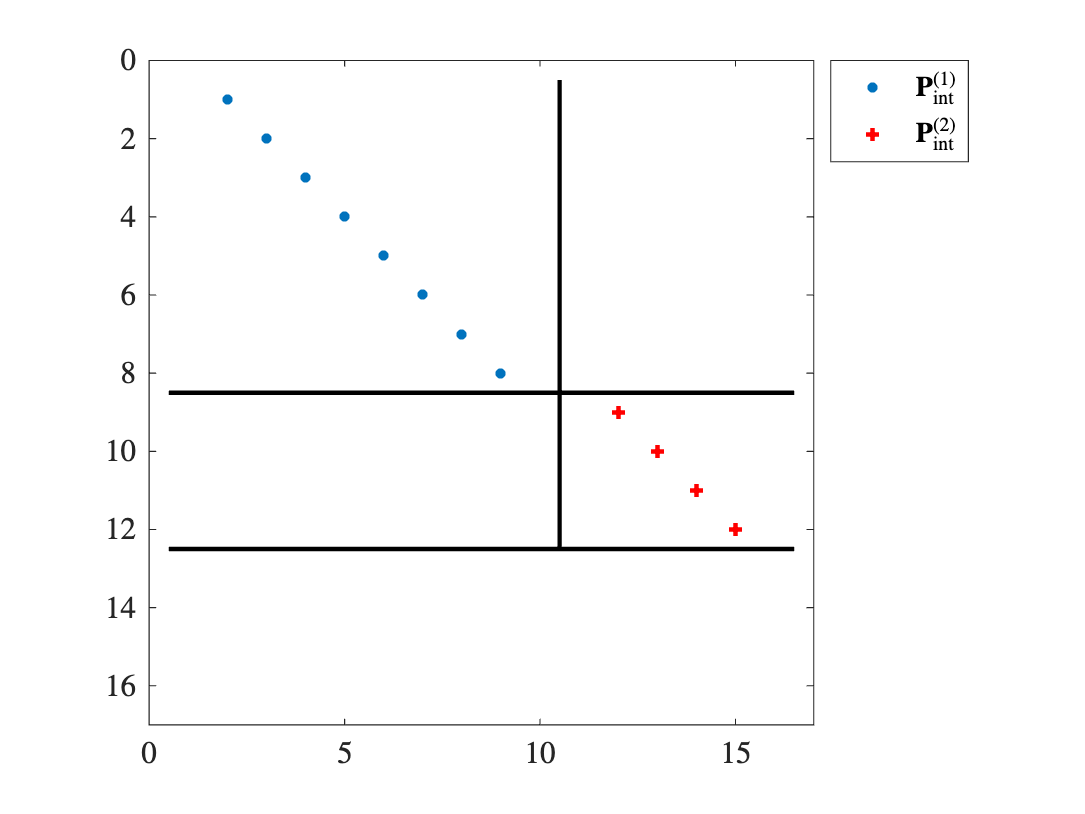


P=G.interpolationMatrixWithZeros;
[Mx,My]=meshgrid(1:16);
clf
spy(P.*(My<=8))
hold on
spy(P.*(8<My).*(My<=12),'r+')
xlabel('')

plot([.5 16.5],8.5*[1 1],'k')
plot([.5 16.5],12.5*[1 1],'k')
plot([10.5 10.5],[.5 12.5],'k')

legend('$\mathbf{P}^{(1)}_{\rm int}$',...
       '$\mathbf{P}^{(2)}_{\rm int}$',...
       'location','northeastoutside')